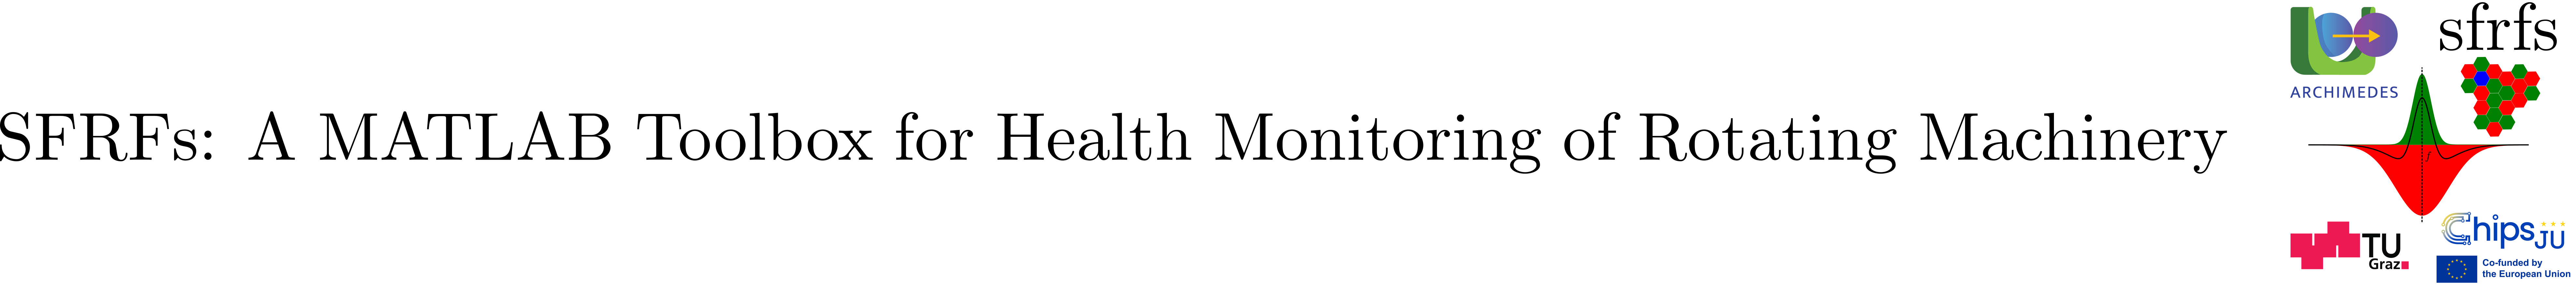

# SuperGaussianMaskParameters

## Summary

`SuperGaussianMaskParameters` defines the configuration parameters for super-Gaussian frequency domain masks used in the SFRFs perceptual pipeline. The super-Gaussian family generalizes Gaussian masking by introducing a shape parameter that controls profile sharpness, allowing smoother or more box like spectral weighting while preserving the same receptive field interpretation. 

## Description

SuperGaussianMaskParameters encapsulates the parameterization of generalized Gaussian (super-Gaussian) frequency domain gain masks independently of their evaluation. A super-Gaussian mask centered at a characteristic frequency $f_c$ is defined as


$$m_G\!\bigl(f ; f_c,\alpha,\beta\bigr)
  = \exp\left(-\left|\frac{f-f_c}{\alpha}\right|^{\beta}\right)\, ,
$$


where $\alpha$ controls the frequency scaling (effective spread) and $\beta$ controls the shape of the profile. The Gaussian mask is recovered as a special case when $\beta = 2$. Increasing $\beta$ produces flatter, more box like profiles, which can improve robustness under finite spectral resolution and FFT bin misalignment. 

This class is intended to be used with `FrequencyMask.evaluate`, providing a clean separation between mask configuration and mask computation, consistent with the parameter object interface used across the toolbox.

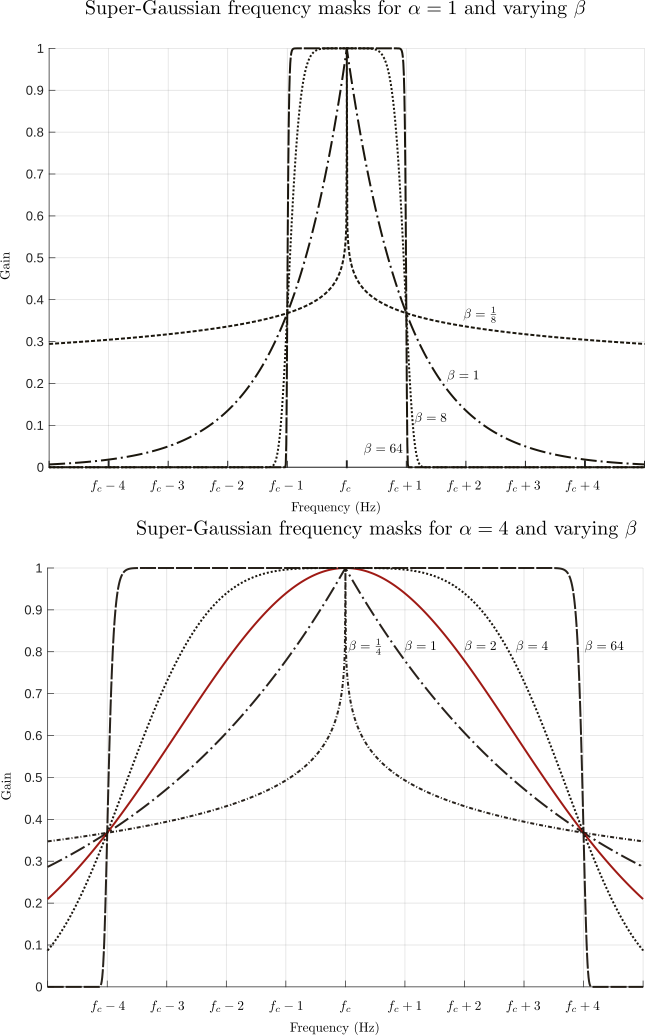

**Figure 1**. Super-Gaussian profiles for different parameter settings. Variation of the scale parameter $\alpha$ controls the effective monitoring bandwidth (top: smaller $\alpha =  1$, narrower profile; bottom: larger $\alpha =  4$ , wider profile). Changing *shape* parameter $\beta$ controls the sharpness of the mask. The Gaussian profile is recovered as the special case $\beta =  2$.

### Properties

### Notes

• This class does not perform mask evaluation itself. 

• SuperGaussianMaskParameters is consumed by FrequencyMask.evaluate to construct super-Gaussian masks.

### See also

[FrequencyMask](matlab:open('./FrequencyMask.mlx')), [GaussianMaskParameters](matlab:open('./GaussianMaskParameters.mlx')), [MaskParameters](matlab:open('./MaskParameters.mlx')) 

## Example

### Evaluate a super-Gaussian mask

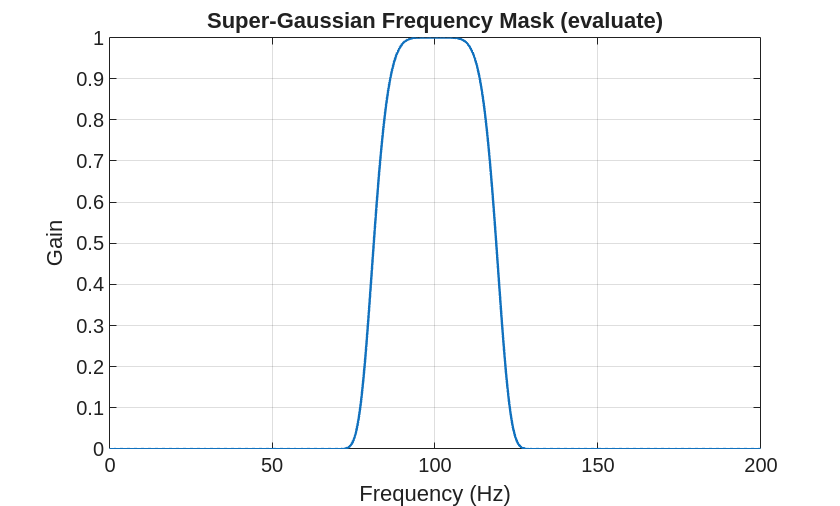

% Frequency axis
f = linspace(0, 200, 2048).';

% Frequency band (used to define a reference width by the evaluator)
band = [80 120];

% Define super-Gaussian mask parameters
params = SuperGaussianMaskParameters( ...
    alpha     = (band(2)-band(1))/2, ...
    beta      = 6);

% Evaluate mask via unified interface
G = FrequencyMask.evaluate(f, band, params);

plot(f, G, "LineWidth", 1.2);
grid on;
xlabel("Frequency (Hz)");
ylabel("Gain");
title("Super-Gaussian Frequency Mask (evaluate)");

### Variation in shape parameter

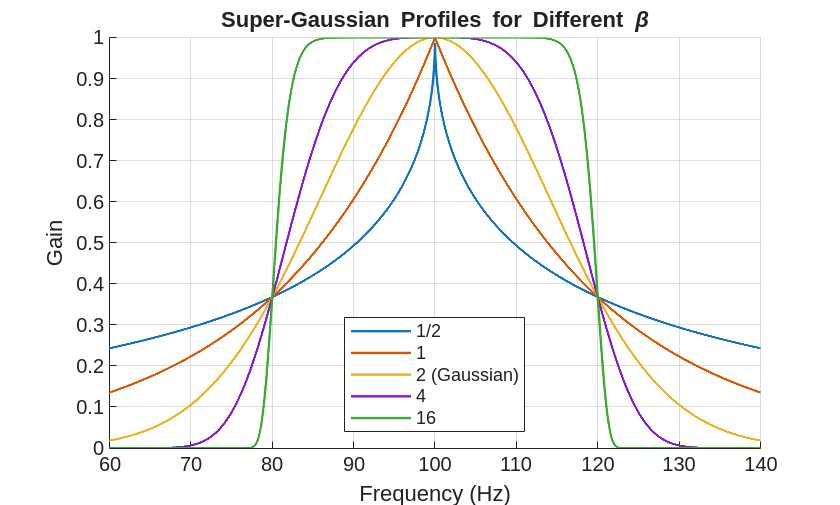

% Frequency axis and band
f = linspace(0, 200, 20000).';
band = [80 120];

alphaVal = (band(2)-band(1))/2;
betaVals = [1/2 1 2 4 16];

figure;
hold on;
grid on;

for k = 1:numel(betaVals)
    params = SuperGaussianMaskParameters( ...
        alpha     = alphaVal, ...
        beta      = betaVals(k));

    G = FrequencyMask.evaluate(f, band, params);
    plot(f, G, "LineWidth", 1.2);
end

xlim([60,140]);
xlabel("Frequency (Hz)");
ylabel("Gain");
title("Super-Gaussian Profiles for Different \beta");
legend("1/2","1", "2 (Gaussian)", "4", "16", "Location", "south");

## API documentation

### MATLAB help

help SuperGaussianMaskParameters

  SuperGaussianMaskParameters
 
  Parameter container for super-Gaussian mask profiles.
 
  The associated (continuous) super-Gaussian mask profile is:
 
    G(f) = exp( - |(f - f_c) / alpha|^beta )
 
  where:
    - f_c    is the mask center frequency (defined externally),
    - alpha  is a positive scale parameter,
    - beta   is a positive shape exponent controlling profile sharpness.
 
  Relation to GaussianMaskParameters:
    The Gaussian mask defined in GaussianMaskParameters corresponds to the
    special case beta = 2 of the super-Gaussian family, where:
 
      Gaussian:       G(f) = exp( -1/2 * ((f - f_c) / sigma)^2 )
      Super-Gaussian: G(f) = exp( - ((f - f_c) / alpha)^2 )
 
    To obtain a super-Gaussian mask equivalent to a Gaussian mask
    parameterized by (bandwidth, sigmaRule):
 
      sigma = bandwidth / (2 * sigmaRule)
      alpha = sqrt(2) * sigma = bandwidth / (sqrt(2) * sigmaRule)
 
    With beta = 2 and this alpha mapping, both masks are ident

## Source code

The source code for the class can be found in [SuperGaussianMaskParameters](matlab:open('./SuperGaussianMaskParameters.mlx')).

## Test

Unit test for the class is implemented in [TestSuperGaussianMaskParameters](matlab:open('../../../tests/TestSuperGaussianMaskParameters.m')).

% execute tests
res = runtests('Spectral Fault Receptive Fields/tests/tests/TestSuperGaussianMaskParameters');

Running TestSuperGaussianMaskParameters
....
Done TestSuperGaussianMaskParameters
__________



% display summary of tests
SFRFsTestUtil.printTestSummary(res,80);

Test Name                                                                        | Result
-----------------------------------------------------------------------------------------
TestSuperGaussianMaskParameters/testDefaultParameters                            | Passed
TestSuperGaussianMaskParameters/testCustomParameters                             | Passed
TestSuperGaussianMaskParameters/testBandwidthProperty                            | Passed
TestSuperGaussianMaskParameters/testValidationErrors                             | Passed



## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery. Zenodo. DOI: [10.5281/zenodo.17631784](http://10.0.20.161/zenodo.17631784).

## References

- [1] Stan Muñoz Gutiérrez and Franz Wotawa. Optimized Spectral Fault Receptive Fields for Diagnosis-Informed Prognosis. In 36th International Conference on Principles of Diagnosis and Resilient Systems (DX 2025). Open Access Series in Informatics (OASIcs), Volume 136, pp. 9:1-9:20, Schloss Dagstuhl – Leibniz-Zentrum für Informatik (2025) [DOI:10.4230/OASIcs.DX.2025.9](https://doi.org/10.4230/OASIcs.DX.2025.9).